# Exercise 2.1 - Dirac Delta and Unit-Step functions

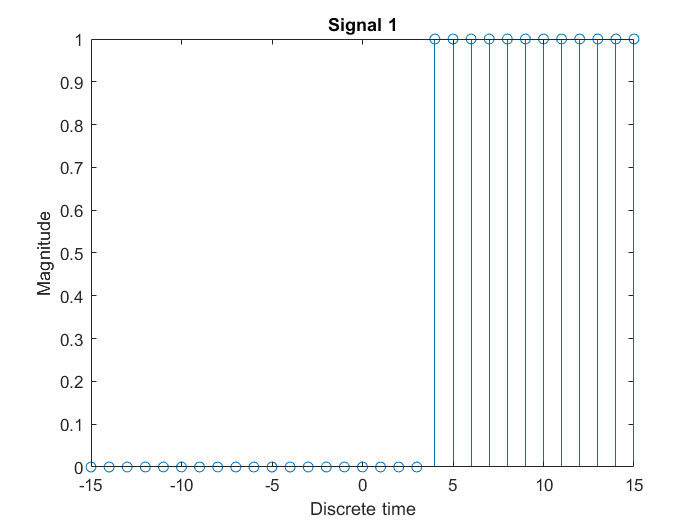

% Let's generate some signals in the -15 ≤ n ≤ 15 interval,
% where n stands for discrete time.
n = -15 : 15;

% Signal #1 (Shifted Unit-Step function)
% u[n - 4]
signal1 = zeros(1, 31);
signal1(n >= 4) = 1;
stem(n, signal1);
title("Signal 1"), xlabel('Discrete time'), ylabel('Magnitude')

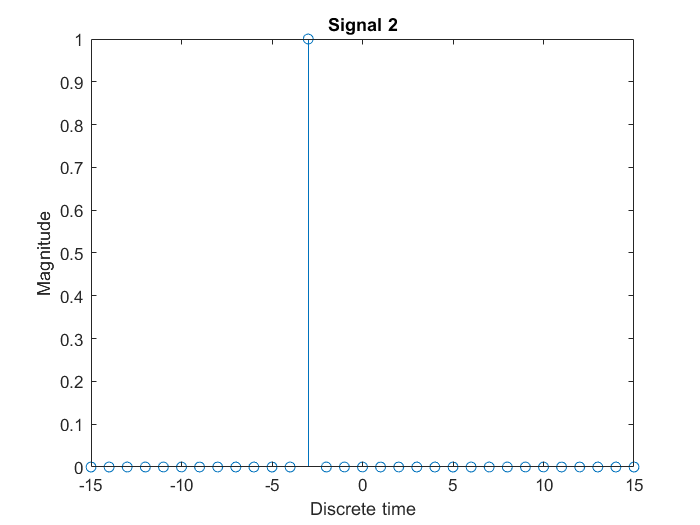



% Signal #2 (Shifted Dirac Delta function)
% δ[n + 3]
signal2 = zeros(1, 31);
n3 = find(n == -3);
signal2(n3) = 1;
stem(n, signal2);
title("Signal 2"), xlabel('Discrete time'), ylabel('Magnitude')

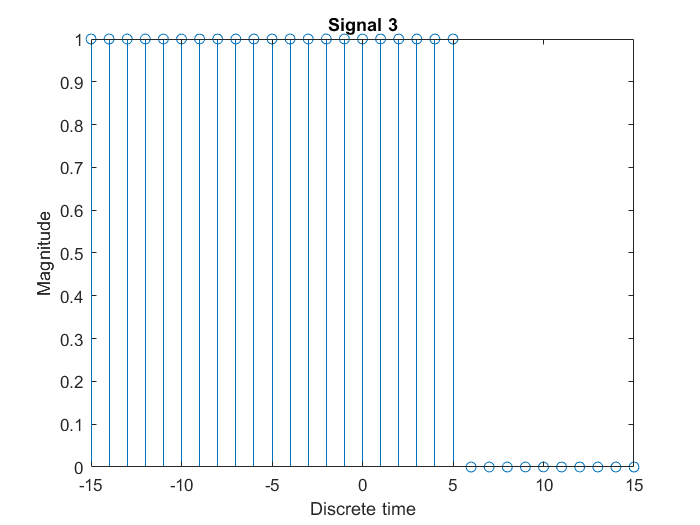


% Signal #3
% u[-n + 5]
signal3 = zeros(1, 31);
signal3(n <= 5) = 1;
stem(n, signal3);
title("Signal 3"), xlabel('Discrete time'), ylabel('Magnitude')

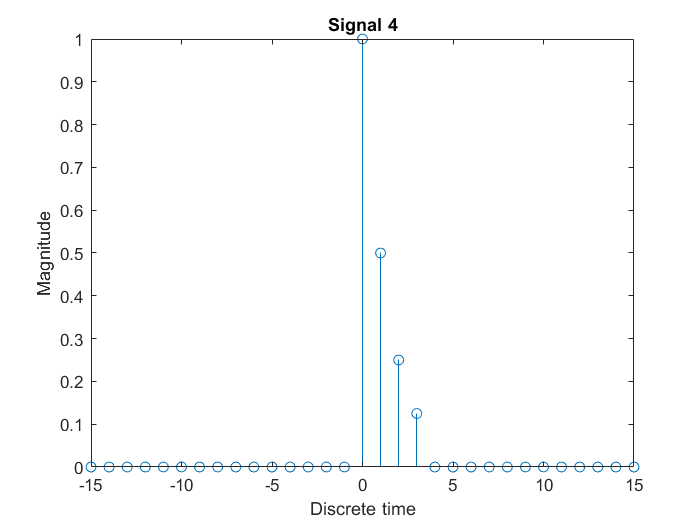


% Signal #4
% 0.51n · (u[n] · u[n − 4])
signal4_1 = zeros(1, 31);
signal4_2 = zeros(1, 31);
signal4_1(n >= 0) = 1;
signal4_2(n >= 4) = 1;
signal4 = (0.5).^n .* (signal4_1 - signal4_2);
stem(n, signal4)
title("Signal 4"), xlabel('Discrete time'), ylabel('Magnitude')

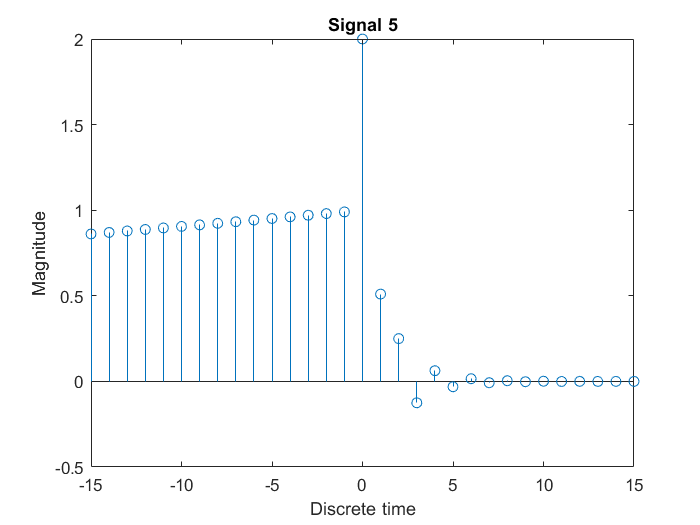


% Signal #5
% (-0.5)n · u[n] + (1.01)n · u[1 - n]
signal5_1 = zeros(1, 31);
signal5_2 = zeros(1, 31);
signal5_1(n >= 0) = 1;
signal5_2(n <= 1) = 1;
signal5 = (-0.5).^n .* signal5_1 + (1.01).^n .* signal5_2;
stem(n, signal5)
title("Signal 5"), xlabel('Discrete time'), ylabel('Magnitude')